# ex2.2

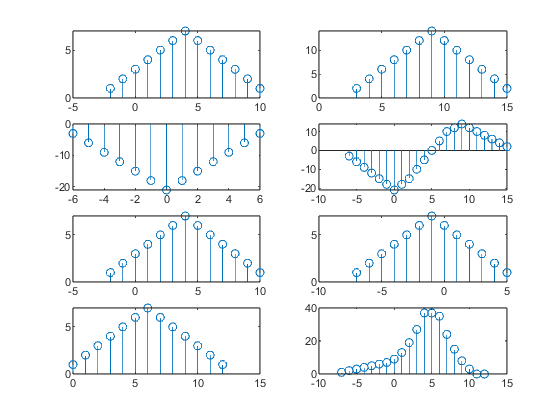

clear;clf
n=-2:10;
x=[1:7,6:-1:1];
subplot(4,2,1);stem(n,x);
[x11,n11]=sigshift(x,n,5);
subplot(4,2,2);stem(n11,2*x11);
[x12,n12]=sigshift(x,n,-4);
subplot(4,2,3);stem(n12,-3*x12);
[x1,n1] = sigadd(2*x11,n11,-3*x12,n12);
subplot(4,2,4);stem(n1,x1);
subplot(4,2,5);stem(n,x);
[x21,n21]=sigfold(x,n);
[x21,n21]=sigshift(x21,n21,3);
subplot(4,2,6);stem(n21,x21);
[x22,n22]=sigshift(x,n,2);
subplot(4,2,7);stem(n22,x22);
[x22,n22]=sigmult(x,n,x22,n22);
[x2,n2]=sigadd(x21,n21,x22,n22);
subplot(4,2,8);stem(n2,x2);

## ex2.3

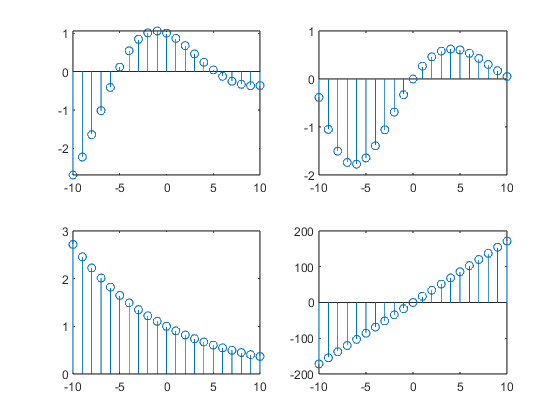

clear;clf;
n=[-10:1:10];
alpha=-0.1+0.3j;
x=exp(alpha*n);
subplot(2,2,1);stem(n,real(x));
subplot(2,2,2);stem(n,imag(x));
subplot(2,2,3);stem(n,abs(x));
subplot(2,2,4);stem(n,(180/pi)*angle(x));

## ex2.4

clear;clf;
n=[0:10];
x=stepseq(0,0,10)-stepseq(10,0,10);
[xe,xo,m]=evenodd(x,n);
subplot(2,2,1);stem(n,x);axis([-10,10,0,1.2])
subplot(2,2,2);stem(m,xe);
subplot(2,2,3);stem(m,xo);

## ex2.9

clear;clf;
x=[3,11,7,0,-1,4,2]

x =      3    11     7     0    -1     4     2


nx=[-3:3]

nx =     -3    -2    -1     0     1     2     3


subplot(2,2,1);stem(nx,x);
h=[2,3,0,-5,2,1];
nh=[-1:4]

nh =     -1     0     1     2     3     4


subplot(2,2,2);stem(nh,h);
[y,ny]=conv_m(x,nx,h,nh)

y =      6    31    47     6   -51    -5    41    18   -22    -3     8     2


ny =     -4    -3    -2    -1     0     1     2     3     4     5     6     7


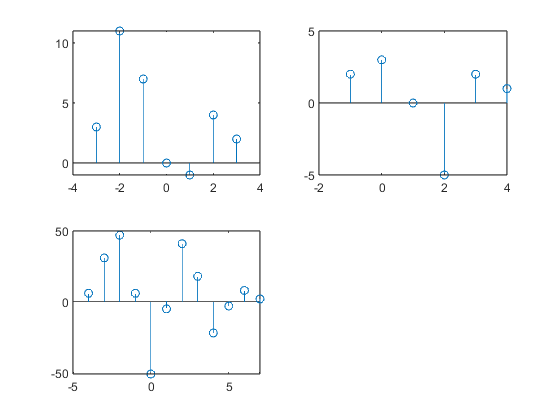

subplot(2,2,3);stem(ny,y);

## ex2.11

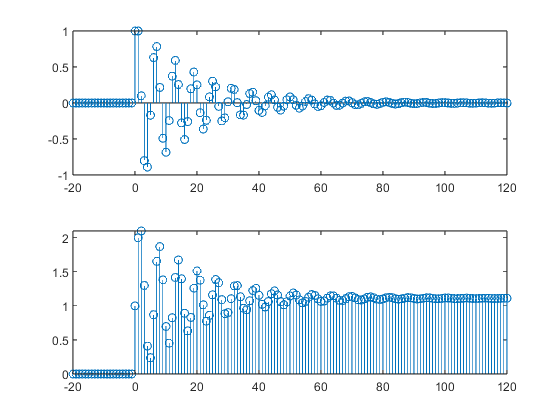

clear;clf;
b=[1];
a=[1,-1,0.9];
n=[-20:120];
h=impz(b,a,n);
subplot(2,1,1);stem(n,h);
x=stepseq(0,-20,120);
s=filter(b,a,x);
subplot(2,1,2);stem(n,s)

## ex2.10

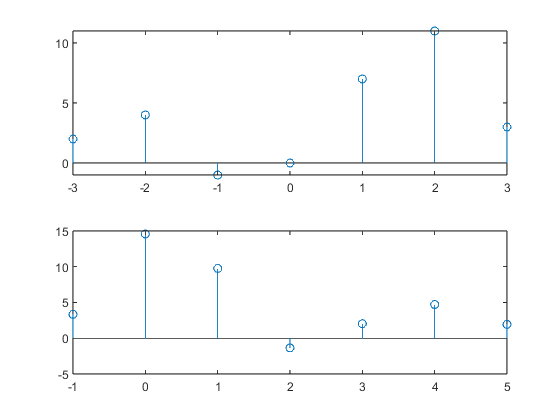

clear;clf;
x=[3,11,7,0,-1,4,2];
nx=[-3:3];
%subplot(2,1,1);
%stem(nx,x);
[y,ny]=sigshift(x,nx,2);
%subplot(2,1,2);
%stem(ny,y);
w=randn(1,length(y));
nw=ny;
[y,ny]=sigadd(y,ny,w,nw);
[x,nx]=sigfold(x,nx);
subplot(2,1,1);
stem(nx,x);
subplot(2,1,2);
stem(ny,y);

## ex3.4.4

Ts=0.0002;Fs=1/Ts;
n=-25:1:25;
nTs=n*Ts;
x=exp(-1000*abs(nTs));
Dt=0.00005;
t=-0.005:Dt:0.005;
xa=x*sinc(Fs*(ones(length(n),1)*t-nTs'*ones(1,length(t))));
error=max(abs(xa-exp(-1000*abs(t))))

error = 0.0363

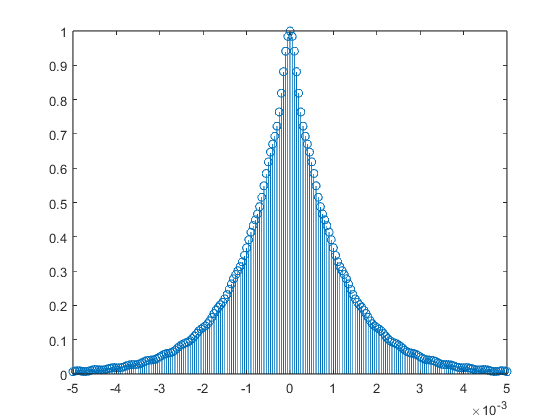

stem(t,xa)

Ts=0.001;Fs=1/Ts;
n=-25:1:25;
nTs=n*Ts;
x=exp(-1000*abs(nTs));
Dt=0.00005;
t=-0.005:Dt:0.005;
xa=x*sinc(Fs*(ones(length(n),1)*t-nTs'*ones(1,length(t))));
error=max(abs(xa-exp(-1000*abs(t))))

error = 0.1852

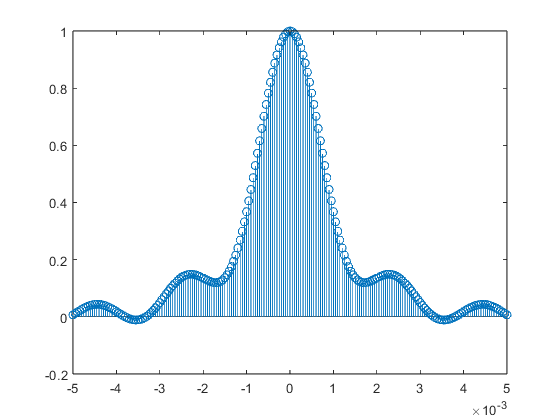

stem(t,xa)

## ex4.8

b=[0,1];a=[3,-4,1];
[R,p,C]=residuez(b,a)

R =     0.5000
   -0.5000


p =     1.0000
    0.3333



C =

     []

